# Counting photons at the sensor surface

We learn a great deal about image quality and noise limits by counting the mean number of photons at each pixel. ISETCam uses physical units throughout, making it straightforward to calculate the number of incident photons at a pixel.  We also learn something by accounting for the fact that the number of photons is Poisson distributed.

This script calculates the mean number of photons we might expect at a pixel in an image sensor.  In ISETCam the image just prior to transduction by the sensor is called the optical image. The initial calculation is for the mean number of photons in a $1\;\mu {\textrm{m}}^2$ patch during 1 sec exposure duration.  Then we calculate the signal-to-noise (mean divided by standard deviation).  We do the calculation at an ambient level of a dimly light classroom.

## Initialize ISETCam 

ieInit

## Create a uniform scene

The luminance level is set to A moderately lit living room at night: Imagine a room with a few lamps on, but not overly bright. If you're  reading a book with a standard table lamp, the page might be closer to 50-100 nits, but the overall average luminance of the entire room (walls, furniture, shadows) could easily be around 10 nits ($\mathrm{cd}/m^2$)

scene = sceneCreate('uniform equal photon',[512 512]);
scene = sceneSet(scene,'mean luminance',10);

## Create spectral irradiance at the sensor for optics with a range of f#

oi = oiCreate('diffraction limited'); 

% Region in the OI we use to measure
roiRect = [291 202 16 23];

% Loop for different f numbers.  Each F/# has an aperture diameter
% that we use, later.
fnumbers = 2:16;

% Store the total number of photons here.
totalQ = zeros(1,length(fnumbers));

% Store the aperture diameter in mm for each fnumber here
apertureD = zeros(size(totalQ));

for ff = 1:length(fnumbers)
    % OI controls focal length and fnumber.  If we set the fnumber,
    % the focal length remains the same.  Hence, only the aperture is
    % changed.  This was a choice that fnumber mattered more than
    % aperture, which is true for ideal lenses.
    oi = oiSet(oi,'optics fnumber',fnumbers(ff));
    oi = oiCompute(oi,scene);
    apertureD(ff) = oiGet(oi,'optics aperture diameter','mm');

    % This is the mean number of photons.
    spectralIrradiance = oiGet(oi,'roi mean photons',roiRect);

    % We sum across all wavelengths.
    totalQ(ff) = sum(spectralIrradiance);
end

## Plot the number of photons as a function of aperture diameter and F/#

This calculation sums the photons of all wavelengths.  Remember that for a color image sensor, we will have to measure different wavebands separately.  And remember that for most applications 1 sec is a long exposure duration.  Cameras typically have a couple of millisecond exposures.

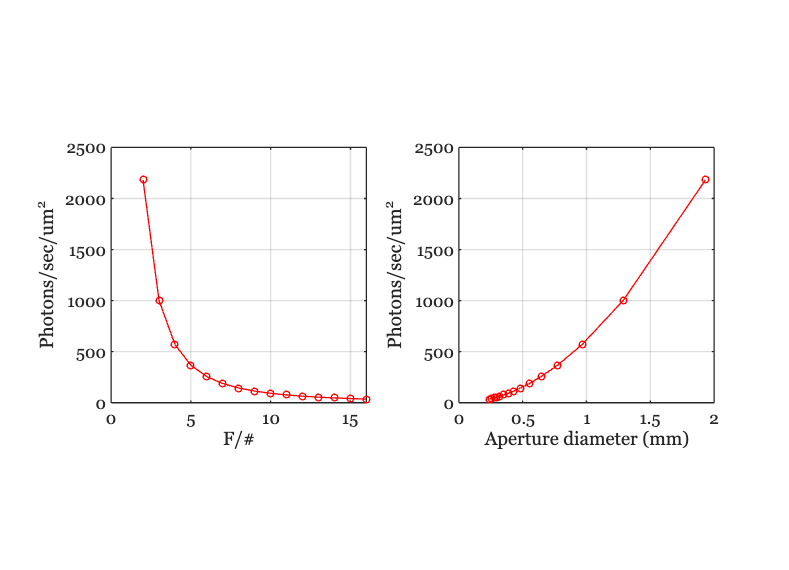

expTime   = 1;        % 1 second
pixelArea = (1e-6)^2; % 1 square micron
sFactor   = pixelArea*expTime;

ieFigure;
subplot(1,2,1);
plot(fnumbers,totalQ*sFactor,'-o'); axis square
grid on; xlabel('F/#'); ylabel('Photons/sec/{um}^2')

subplot(1,2,2);
plot(apertureD,totalQ*sFactor,'-o'); axis square
grid on; xlabel('Aperture diameter (mm)'); ylabel('Photons/sec/{um}^2')

## Signal-to-noise as a function of F/#

The signal-to-noise is the ratio of the signal level to the signal standard deviation.  This tells us how many standard deviations the signal is from absolute noise. For this calculation, we use a more realistic exposure time of 50 milliseconds.  This is about the duration of the impulse response of a human cone photoreceptors.  In the central fovea, the aperture of such a receptor is about $1\;\mu {\textrm{m}}^2$

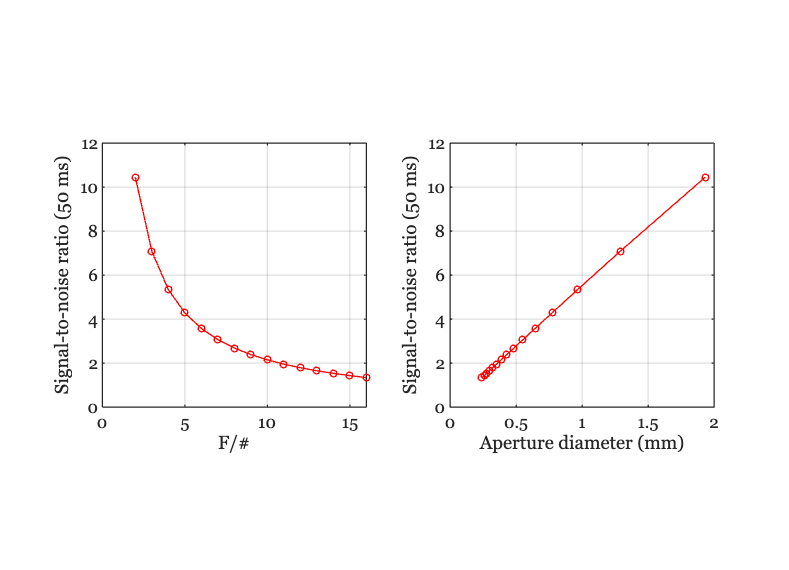

expTime = 0.050;
sFactor = pixelArea*expTime;
SNR = totalQ*sFactor ./ sqrt(totalQ*sFactor);

ieFigure;
subplot(1,2,1);
plot(fnumbers,SNR,'-o'); axis square
grid on; xlabel('F/#'); 
ylabel(sprintf('Signal-to-noise ratio (%d ms)',expTime*1e3));

subplot(1,2,2)
plot(apertureD,SNR,'-o'); axis square
grid on; xlabel('Aperture diameter (mm)'); 
ylabel(sprintf('Signal-to-noise ratio (%d ms)',expTime*1e3));